# Setup and Variable Parameters

clc
clear
warning('off','all')

%Plant
Cu = 21e-12;
I = 4.971e-12;
G_plant = tf(Cu,[I 0]) %Torque to Velocity


G_plant =
 
    2.1e-11
  -----------
  4.971e-12 s
 
Continuous-time transfer function.




%V_set = .1*ones(1,size(t,2)); %step
%unitstep = t>=0;

# Simulate Case 1

Case 1 is a simple ramp to show the basic functionality of the hybrid controller

%Input
N_temp = 10;
delta_t = 0.001;
t = 0:delta_t:N_temp;
rampmag = 50/N_temp;
V_set = rampmag*t;
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)

Model 'HybridSaccadeFF' was created with a newer version (R2020a) of Simulink
To disable this error message, use Simulink preferences.
To create a model that is compatible with this version of Simulink, load the model in Simulink R2020a and select File > Export Model to > Previous Version.

set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = 0.3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .05; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 100; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gt',rampmag)
fprintf('Neurological Delay: %g',n_delay)
fprintf('Saccade Completion "Delay:" %g',sac_time)
fprintf('Integrated Error Switching Threshold: %g',switch_thresh)
fprintf('Smooth System Proportional Gain: %g',K_P)
fprintf('Smooth System Integral Gain: %g',K_I)

figure
plot(out.tout,out.V_out,t,V_set)

We can see the functionality of the controller in this simple ramp plot.  The smooth controller runs until hitting the integrated error threshold, after which the output is held steady while the saccade "executes."  After the saccade completes, the smooth controller is re-engaged.  Let's take a closer look:

figure
plot(out.tout,out.V_out,t,V_set)
xlim([2 5])
annotation('textarrow',[0.35 0.3],[.3 0.41],'String','Smooth Region')
saccadenote = "Saccade Execution" + newline + "(output held)";
annotation('textarrow',[0.6 0.55],[.35 0.43],'String',saccadenote)
annotation('textarrow',[0.65 0.59],[.5 0.587],'String',"Open Loop Saccade")
smoothnote = "Return to" + newline + "Smooth Control";
annotation('textarrow',[0.71 0.65],[.75 0.678],'String',smoothnote)


# Simulate Case 2

Cases 2-6 are variations on a slow sin wave input.

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = 0.3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .005; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.005

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

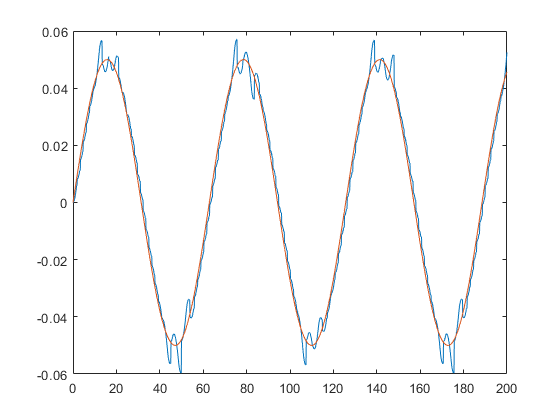


figure
plot(out.tout,out.V_out,t,V_set)

We will use this as the baseline for exploring some parameter changes with the slow sine wave input.  We can see that the output tracks the sin wave with some interesting excursions around the peaks.

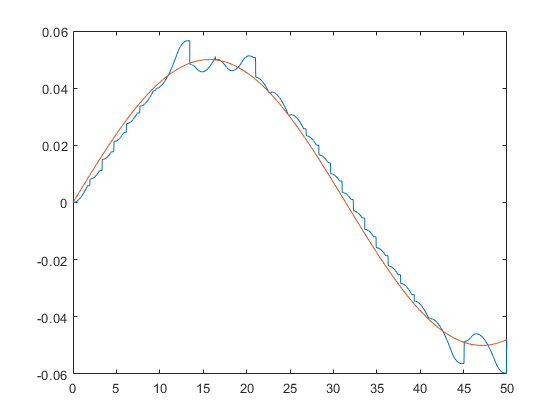

figure
plot(out.tout,out.V_out,t,V_set)
xlim([0 50])

Zooming in to the first wave we can see that the rising and falling around the peak have a similar response as the ramp.  Around the peak the saccade has a "stabilizing" effect - pulling the response back in line with the curve when it escapes too far.  We will explore this effect in several other cases.

# Simulate Case 3

Case 3 is the same as Case 2, but with an increased Saccade Completion time (0.3 second to 3 seconds)

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = 3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .005; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.005

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

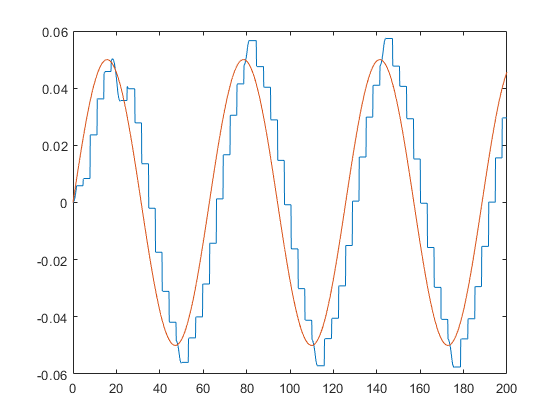


figure
plot(out.tout,out.V_out,t,V_set)

A larger saccade execution time (delay) results in a response that is largely saccadic with few smooth movements.  Because the saccade takes so long to execute, the final value is far away from the input wave.  When the smooth controller takes back over, it quickly accumulates enough error to switch the system back over to the saccadic system.

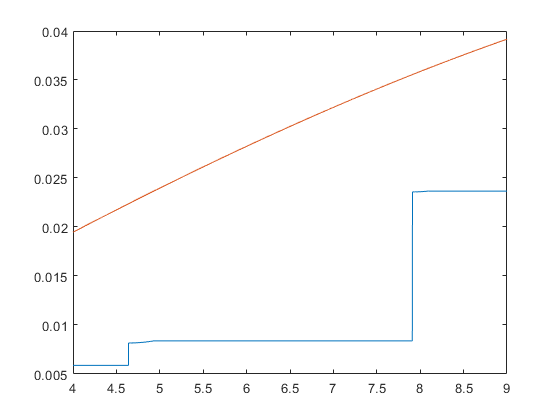

figure
plot(out.tout,out.V_out,t,V_set)
xlim([4 9])

Zooming in, we can see that the saccade "corners" are rounded from the transition to the smooth controller, but the switch back occurs very quickly.  Increasing the switching threshold gives a more varied response as the error must accumulate more to trigger a saccade:

%Parameters
sac_time = 3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .05; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.05

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

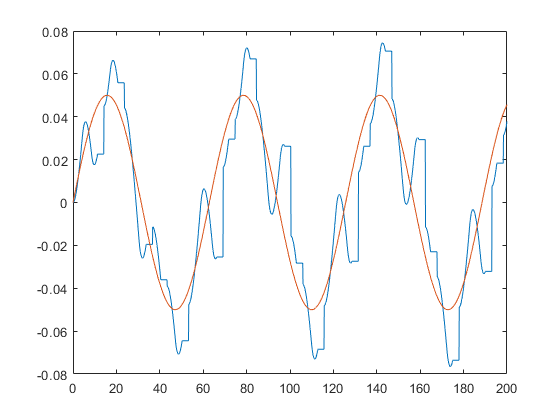


figure
plot(out.tout,out.V_out,t,V_set)

# Simulate Case 4

Case 4 is the same as Case 2, but with an increased switching threshold (integrated error) (0.005 to 0.05)

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .5; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.5

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

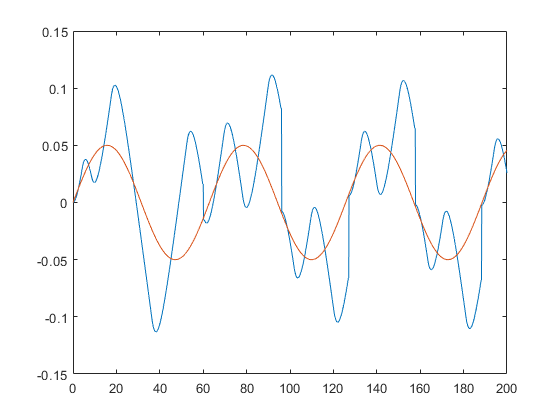


figure
plot(out.tout,out.V_out,t,V_set)

By increasing the integrated error switching threshold to initiate a saccade, we can see that the response leans more into the smooth regime.  We can see again that the saccades have a stabilizing effect on the controller - even if the smooth controller is unstable, the saccades will stabilize it because they pull the controller back to a zero state, resetting the integrator and "rebasing" the controller.

In this way the hybrid system follows the paradigm of "jumps" and flows."  That is, the system flows through the smooth controller states, but the saccade jumps the system from one state to another discontinuously.

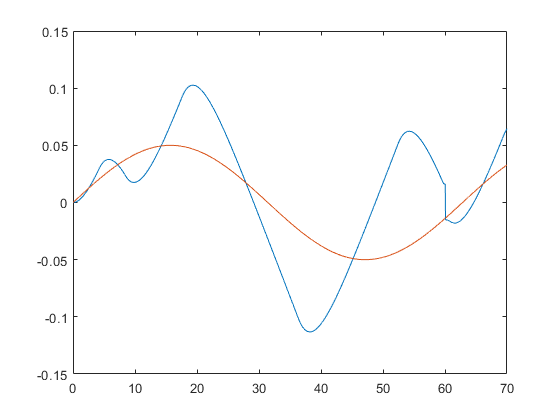

figure
plot(out.tout,out.V_out,t,V_set)
xlim([0 70])

Zooming in we can better see the transition between the smooth and saccade portion of the system.  The system flows until the switching threshold is met, after which is jumps to a new state and begins flowing again.  Again - the system is stabilized by the saccades.  Let's take a look at two more increases in error threshold - to 0.5 and 5.

%Parameters
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .5; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.5

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10


figure
plot(out.tout,out.V_out,t,V_set)


%Parameters
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = 5; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 5

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

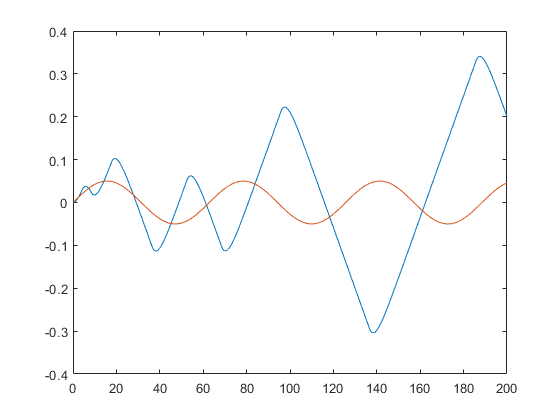


figure
plot(out.tout,out.V_out,t,V_set)

By increasing the saccade switching threshold, the excursions become larger and larger until the response goes unstable (at least in this timeframe - with a finite switching threshold the system will always be quasi-stable, since the saccade will initiate within finite time, bringing the system back to the input).

# Simulate Case 5

Case 5 is the same as Case 2, but with a decreased Proportional Gain (10 to 1)

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .005; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 1; %Proportional Gain
K_I = 10; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.005

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 1

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 10

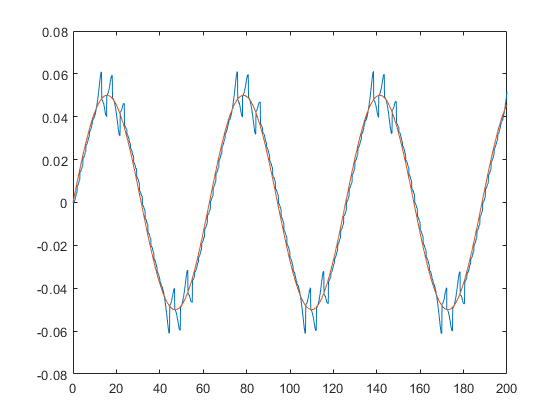


figure
plot(out.tout,out.V_out,t,V_set)

Decreasing the proportional gain increases the impact of the integral portion of the smooth controller.  Again, the ramp portions of the input wave are tracked closely, with excursions around the directional changes at the peaks.

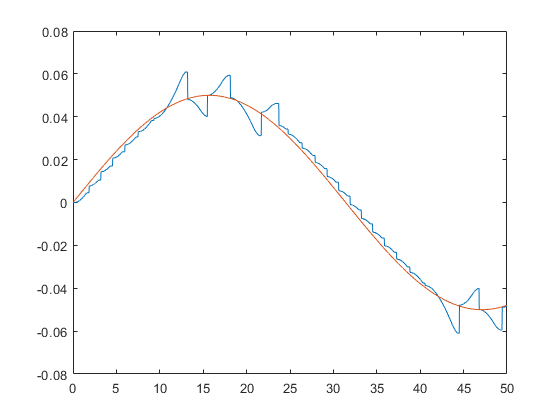

figure
plot(out.tout,out.V_out,t,V_set)
xlim([0 50])

# Simulate Case 6

Case 6 is the same as Case 2, but with a decreased Integral Gain (10 to 1)

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 3e-3; %Biological Torque Limit upper
T_lim_low = -3e-3; %Biological Torque Limit upper
switch_thresh = .005; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = 10; %Proportional Gain
K_I = 1; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.005

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 10

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 1

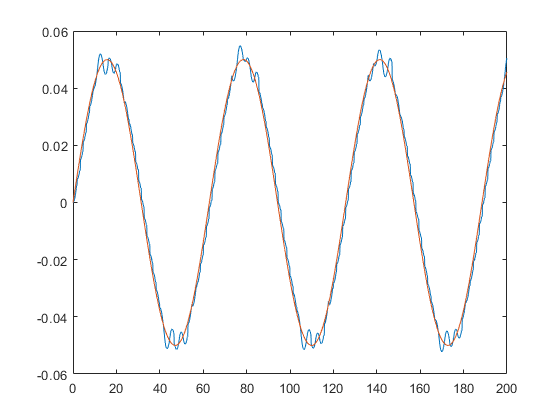


figure
plot(out.tout,out.V_out,t,V_set)

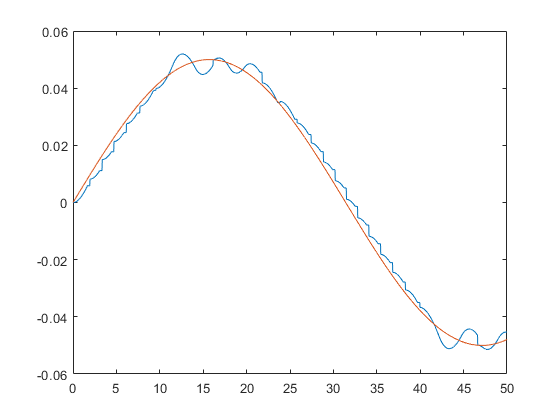


figure
plot(out.tout,out.V_out,t,V_set)
xlim([0 50])

# Sandbox

This is a section where different parameter sets can be tried out.

%Input
N_temp = 200;
delta_t = 0.001;
t = 0:delta_t:N_temp;
sinmag = 0.05;
sinfreq = .1;
V_set = sinmag*sin(sinfreq*t);
V_in = [t' V_set'];

%Model Setup
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Parameters (EDIT THESE)
sac_time = .3; %Saccade completion "delay"
n_delay = .3; %Neurological Delay
T_lim_up = 100; %Biological Torque Limit upper
T_lim_low = -100; %Biological Torque Limit upper
switch_thresh = .05; %Integrated error threshold for switching between smooth/saccadic
sac_thresh = .1; %Position error threshold for finishing saccade
K_P = .1; %Proportional Gain
K_I = .005; %Integral Gain of smooth system

out = sim('HybridSaccadeFF.slx','AlgebraicLoopMsg', 'off');

fprintf('Input : %gsin(%gt)',sinmag,sinfreq)

Input : 0.05sin(0.1t)

fprintf('Neurological Delay: %g',n_delay)

Neurological Delay: 0.3

fprintf('Saccade Completion "Delay:" %g',sac_time)

Saccade Completion "Delay:" 0.3

fprintf('Integrated Error Switching Threshold: %g',switch_thresh)

Integrated Error Switching Threshold: 0.05

fprintf('Smooth System Proportional Gain: %g',K_P)

Smooth System Proportional Gain: 0.1

fprintf('Smooth System Integral Gain: %g',K_I)

Smooth System Integral Gain: 0.005

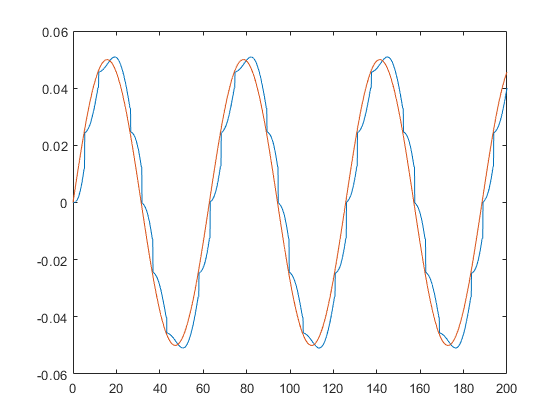


figure
plot(out.tout,out.V_out,t,V_set)

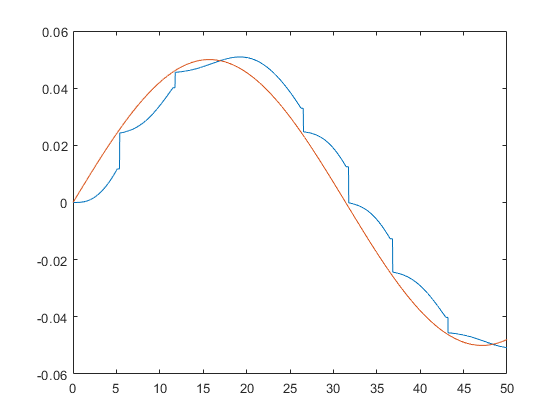


figure
plot(out.tout,out.V_out,t,V_set)
xlim([0 50])